%fazer plot da funcao
funcao=@(x1,x2) ((x1.^2 + x2 - 11).^2 + (x1 + x2.^2 - 7).^2);
j1 =@(x1,x2)(4.*x1.^3+4.*x1.*x2-42.*x1+2.*x2.^2-14);
j2=@(x1,x2)(4.*x2.^3+4.*x1.*x2-26.*x2+2.*x1.^2-22);


x1 = linspace(-4,4,100);
x2 = linspace(-4,4,100);
[x1,x2] = meshgrid(x1,x2);
Z2 = sqrt(j1(x1,x2).^2+j2(x1,x2).^2);
surf(x1,x2,Z2)

surf(x1,x2,Z2)

figure; surf(x1,x2,Z2)



%a
%correr os pontos 
format long

[x1 x2 t iter] = Newton(-3.75758,-3.19192,10^(-6),100000)

format long

[x1 x2 t iter] = Newton(-3.0303,-0.040404,10^(-6),100000)

format long

[x1 x2 t iter] = Newton(-2.78788,3.27273,10^(-6),100000)

format long

[x1 x2 t iter] = Newton(-0.121212,-1.0101,10^(-6),100000)

format long

[x1 x2 t iter] = Newton(0.121212,2.94949,10^(-6),100000)

format long

[x1 x2 t iter] = Newton(3.51515,0.121212,10^(-6),100000)

format long

[x1 x2 t iter] = Newton(3.0303,2.22222,10^(-6),100000)

format long

[x1 x2 t iter] = Newton(3.67677,-1.81818,10^(-6),100000)

%b
format long

[x t iter] = Algoritmo1(-3.75758,-3.19192,10^(-6),100000)

format long

[x t iter] = Algoritmo1(-3.0303,-0.040404,10^(-6),100000)

format long

[x t iter] = Algoritmo1(-2.78788,3.27273,10^(-6),100000)

format long

[x t iter] = Algoritmo1(-0.121212,-1.0101,10^(-6),100000)

format long

[x t iter] = Algoritmo1(0.121212,2.94949,10^(-6),100000)

format long

[x t iter] = Algoritmo1(3.51515,0.121212,10^(-6),100000)

format long

[x t iter] = Algoritmo1(3.0303,2.22222,10^(-6),100000)

format long

[x t iter] = Algoritmo1(3.67677,-1.81818,10^(-6),100000)


%c
format long

[x t iter matriza] = Algoritmo1c(3.67677,-1.81818,10^(-12),100000)

[x1 x2 t iter matrizn] = Newtonc(3.67677,-1.81818,10^(-12),100000)







%faz lista dos erros
xreal = [3.584428340330; -1.848126526964];

errosn = zeros(1, size(matrizn, 2));
for k = 1:size(matrizn, 2)
    errosn(k) = norm(matrizn(:, k) - xreal, 2);
end


p = [];
for k = 2:length(errosn)-1
    %casas decimais do format long
    if errosn(k+1) > 1e-15 && errosn(k) > 1e-15 && errosn(k-1) > 1e-15
        n = log(errosn(k+1)/errosn(k));
        d = log(errosn(k)/errosn(k-1));
        p(end+1) = n/d;
    end
end
p
C = [];

for k = 2:length(errosn)-1
    if errosn(k) > 1e-15
        % Usamos o p calculado para a iteração específica
        C(end+1) = errosn(k+1) / (errosn(k)^2);
    end
end
C



xreal = [3.584428340330; -1.848126526964];


errosa = zeros(1, size(matriza, 2));
for k = 1:size(matriza, 2)
    errosa(k) = norm(matriza(:, k) - xreal, 2);
end


p = [];
for k = 2:length(errosa)-1
    %casas decimais do format long
    if errosa(k+1) > 1e-15 && errosa(k) > 1e-15 && errosa(k-1) > 1e-15
        n = log(errosa(k+1)/errosa(k));
        d = log(errosa(k)/errosa(k-1));
        p(end+1) = n/d;
    end
end

p

matrizn
matriza


format long

[x t iter matriza] = Algoritmo1c(5,-4,10^(-12),100000)

[x1 x2 t iter matrizn] = Newtonc(5,-4,10^(-12),100000)




% (d)

clc
clear

eps = 1e-12;
k = 1000;
x0 = [4.0; -1.0];
xstar = [3.584428340330; -1.848126526964];

[x,t,iter,eA,eS,eP] = Algoritmo1d(x0(1),x0(2),eps,k,xstar);

x

x =     3.5844
   -1.8481


t

t = "minimo"

iter

iter = 15

eA

eA =    41.5858  582.0305  583.0938  226.0672   23.0992    5.7958   11.8934   13.2519    5.7973    5.7974    5.7970    5.7974    5.8756    0.0070    0.0000


eS

eS =    27.7097  581.2224  191.4741  118.4236   22.7888    5.2839   11.8914   13.2518    2.0633    2.2714    0.5353    0.0724    1.9417    0.0066    0.0000


eP

eP =    11.5724    1.0804    0.0680    0.0989    2.1619    1.4950    0.4880    1.5518    1.1816    0.9108    1.0174    1.0015    0.9934    0.9995    0.1319


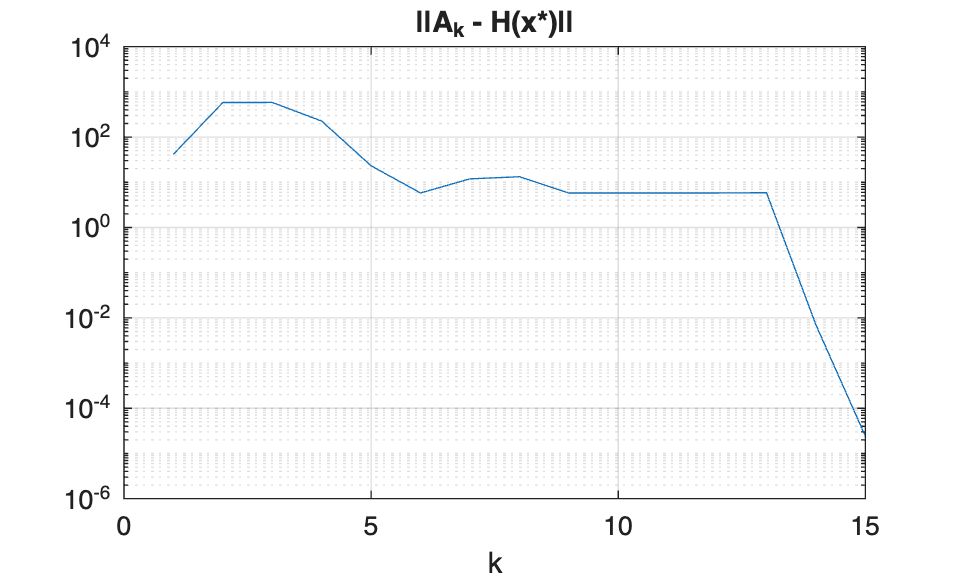


figure
semilogy(1:iter, eA)
title('||A_k - H(x*)||')
xlabel('k')
grid on

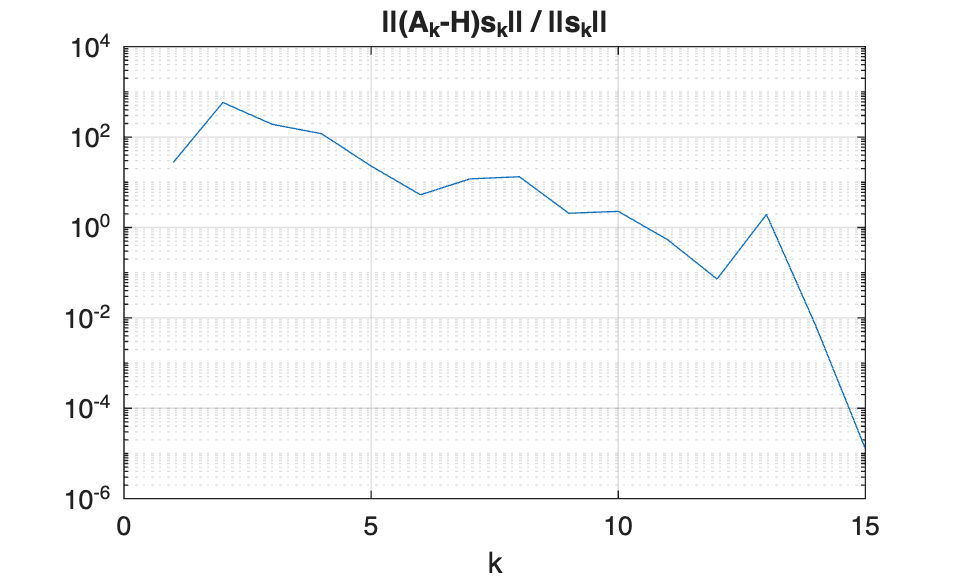

%saveas(gcf, '2d_eA.png')

figure
semilogy(1:iter, eS)
title('||(A_k-H)s_k|| / ||s_k||')
xlabel('k')
grid on

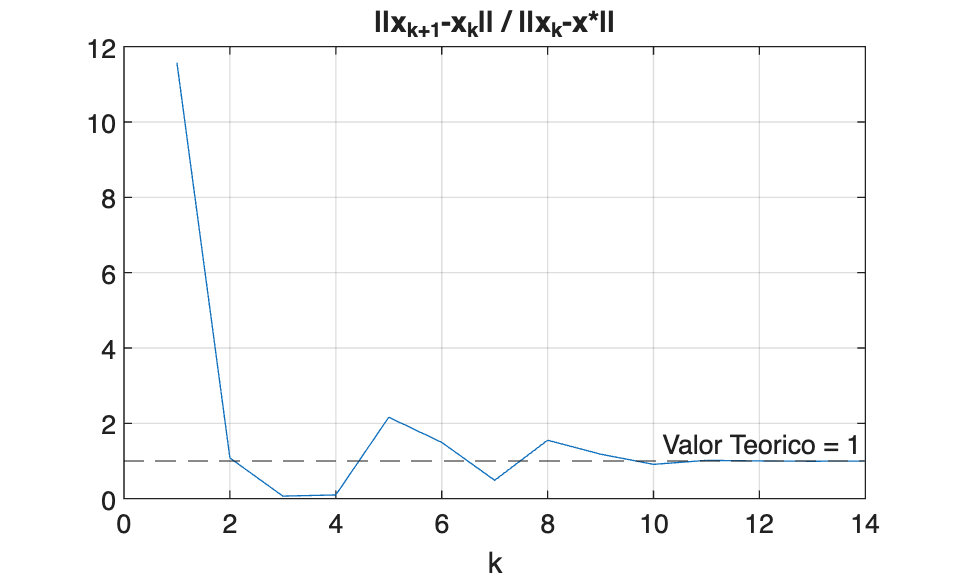

%saveas(gcf, '2d_eS.png')

eP_plot = eP(1:end-1);
figure
plot(eP_plot)
yline(1, '--', 'Valor Teorico = 1')
title('||x_{k+1}-x_k|| / ||x_k-x*||')
xlabel('k')
grid on

%saveas(gcf, '2d_eP.png')

% (e)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%555
format long 
x0 = [2.9;1.9];
z = [3;2];


h = @ (p,q) ([12.*p.^2+4.*q-42 4.*p+4.*q;4.*p+4.*q 12.*q.^2+4.*p-26]);
F = @ (p,q) ([4.*p.^3+4.*p.*q-42.*p+2.*q.^2-14;4.*q.^3+4.*p.*q-26.*q+2.*p.^2-22]);
G = @(x) -inv(h(x(1),x(2)))*F(x(1),x(2)) + x;

[xn matrizf] = metodopontofixo(10^-4, x0) % converge para valores proximos de (3,2)



% estimativa para o coeficiente assintotico do metodo do ponto fixo proposto
format long
xn1 = G(xn)
norm(z - xn1)./norm(z - xn)


% Calcular o erro de cada iteração comparado com a solução z
errosf = zeros(1, size(matrizf, 2));
for k = 1:size(matrizf, 2)
    errosf(k) = norm(matrizf(:, k) - z, 2);
end

p = [];
for k = 2:length(errosf)-1
    % Evitar divisão por zero ou log de números muito pequenos
    if errosf(k+1) > 1e-15 && errosf(k) > 1e-15 && errosf(k-1) > 1e-15
        n = log(errosf(k+1)/errosf(k));
        d = log(errosf(k)/errosf(k-1));
        p(end+1) = n/d;
    end
end

p

C = [];

for k = 2:length(errosf)-1
    if errosf(k) > 1e-15
        % Usamos o p calculado para a iteração específica
        C(end+1) = errosf(k+1) / (errosf(k)^2);
    end
end
C


%c
format long


[x1 x2 t iter matrizn] = Newtonc(2.9,1.9,10^(-12),100000)
[x t iter matriza] = Algoritmo1c(2.9,1.9,10^(-12),100000)

x0 = [2.9;1.9];

 [xn matrizf] = metodopontofixo(10^-12, x0)




format long
z = [3; 2];
x0 = [2.5; 2.5];

 [xn matrizf] = metodopontofixo(10^-12, x0)



%c
format long


[x1 x2 t iter matrizn] = Newtonc(3,1,10^(-12),100000)
[x t iter matriza] = Algoritmo1c(3,1,10^(-12),100000)

x0 = [3;1];

 [xn matrizf] = metodopontofixo(10^-12, x0)




